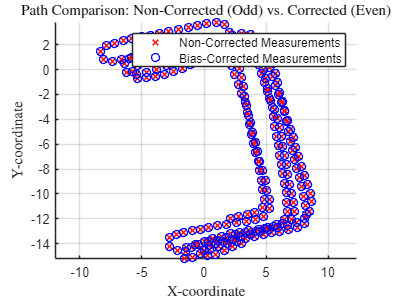

clear;
clc;

% Define the file name
filename = 'PDR_STC_Test6.txt';

% Initialize arrays to hold the x and y data
x_all = [];
y_all = [];
x_corrected = [];
y_corrected = [];

% Open the file for reading
fid = fopen(filename, 'r');

% Check if the file was opened successfully
if fid == -1
    error('File could not be opened. Check the filename and path.');
end

% Read the file line by line
lineIndex = 1; % Initialize line counter
while ~feof(fid)
    line = fgetl(fid); % Read one line
    % Extract the x and y values using regular expressions
    tokens = regexp(line, 'x = (?<x>-?\d+\.\d+), y = (?<y>-?\d+\.\d+)', 'tokens');
    if ~isempty(tokens) % Check if the line contained the coordinates
        x_all(end+1) = str2double(tokens{1}{1});
        y_all(end+1) = str2double(tokens{1}{2});
        
        if mod(lineIndex, 2) == 0 % Check if line number is even
            % Store bias-corrected (even) measurements
            x_corrected(end+1) = x_all(end);
            y_corrected(end+1) = y_all(end);
        end
    end
    lineIndex = lineIndex + 1; % Increment line counter
end

x = x_all(1:2:end);
y = y_all(1:2:end);

x_sim = zeros(500, 1);
y_sim = zeros(500, 1);

% Initialize starting position and heading (facing west)
x_sim(1:2) = 0;
y_sim(1:2) = 0;
psi = atan2(y(1)-y(2), x(1)-x(2)); % Starting heading west
rng(1);

for idx = 2:length(x)
    % Placeholder: Assume the initial heading is directly towards the second data point
    if idx == 2
        psi = atan2(y(2)-y(1), x(2)-x(1));
    else
        % Calculate the bias angle
        psi_bias = atan2(y(idx-2)-y(idx-1), x(idx-2)-x(idx-1)) - atan2(y(idx-1)-y(idx), x(idx-1)-x(idx));
        % Update the heading
        psi = psi - psi_bias;
    end
    
    % Set the step length with a small random noise
    lambda = 0.7 + normrnd(0, 0.1);
    
    % Update position
    x_sim(idx) = x_sim(idx-1) + lambda*cos(psi);
    y_sim(idx) = y_sim(idx-1) + lambda*sin(psi);
end

% Close the file
fclose(fid);

% Plot the bias-corrected (even) and non-corrected (odd) data points
figure;
hold on;
plot(x_all(449:2:end), y_all(449:2:end), 'rx', 'LineWidth', 1, 'MarkerSize', 6); % Non-corrected (odd)
plot(x_all(450:2:end), y_all(450:2:end), 'bo', 'LineWidth', 1, 'MarkerSize', 6); % Corrected (even)
% plot(x_sim, y_sim, 'bo', 'LineWidth', 1, 'MarkerSize', 6)
title('Path Comparison: Non-Corrected (Odd) vs. Corrected (Even)');
xlabel('X-coordinate');
ylabel('Y-coordinate');
legend('Non-Corrected Measurements', 'Bias-Corrected Measurements');
grid on;
axis equal;
hold off;


% Test
% % Calculate the bias angle
% psi_bias = atan2(y(idx-2)-y(idx-1), x(idx-2)-x(idx-1)) - atan2(y(idx-1)-y(idx), x(idx-1)-x(idx));
% % Update the heading
% psi = psi - psi_bias;